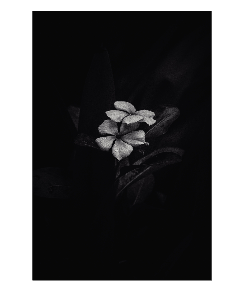

img=imread('pexels-sharath-giri-3849160.jpg'); 
imshow(img);

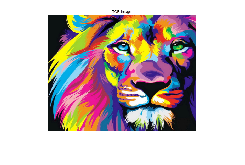

a=imread('rgb.png');
imshow(a)

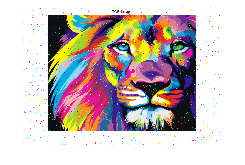

j =  imnoise(a,'salt & pepper',0.02);
figure
imshow(j)

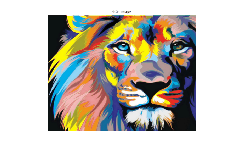

j=medfilt3(a);
imshow(j);

average=fspecial('average',3)

average =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


average_filtered_rgb_table=imfilter(j,average)

average_filtered_rgb_table = 525×751×3 uint8 array
average_filtered_rgb_table(:,:,1) =

   113   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170

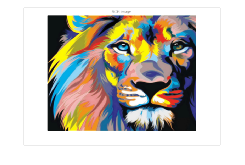

imshow(average_filtered_rgb_table);

gaussian=fspecial('gaussian',3)

gaussian =     0.0113    0.0838    0.0113
    0.0838    0.6193    0.0838
    0.0113    0.0838    0.0113


gaussian_filtered_rgb_table=imfilter(a,gaussian)

gaussian_filtered_rgb_table = 525×751×3 uint8 array
gaussian_filtered_rgb_table(:,:,1) =

   204   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   2

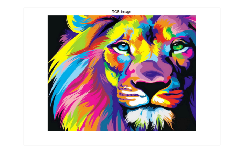

imshow(gaussian_filtered_rgb_table)

h = fspecial('log',3,0.4)

h =     0.7948    1.6739    0.7948
    1.6739   -9.8745    1.6739
    0.7948    1.6739    0.7948


log_filtered_rgb_table=imfilter(a,h)

log_filtered_rgb_table = 525×751×3 uint8 array
log_filtered_rgb_table(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

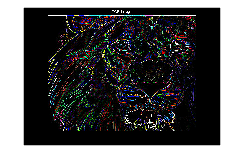

imshow(log_filtered_rgb_table)

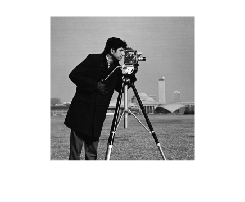

I = imread('cameraman.tif');
imshow(I)

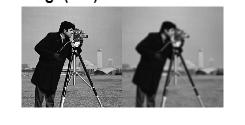

Iblur = imgaussfilt(I,2);
montage({I,Iblur})
title('Original Image(left) Vs. Gaussian Filter(right)')

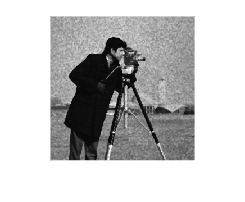

k = imnoise(I,'speckle',0.02);
j=medfilt2(k);
imshow(j)

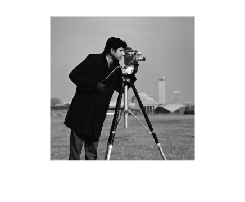

k = imnoise(I,'salt',0.02);
j=medfilt2(k);
imshow(j)

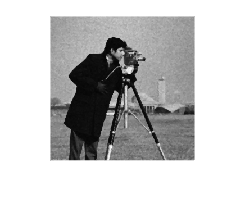

k = imnoise(I,'poisson');
j=medfilt2(k);
imshow(j)

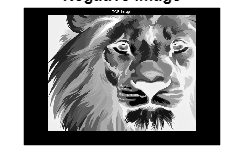

k=rgb2gray(a);
neg=255-k;
imshow(neg); title('Negative Image');

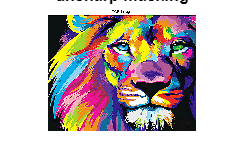

unsharp=fspecial('unsharp');
b=imfilter(a,unsharp);
imshow(b);
title('unsharp masking');

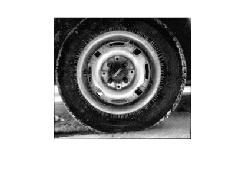

tire = imread("tire.tif");
tire_imadjust = imadjust(tire);
tire_histeq = histeq(tire);
tire_adapthisteq = adapthisteq(tire);
imshow(tire_adapthisteq);